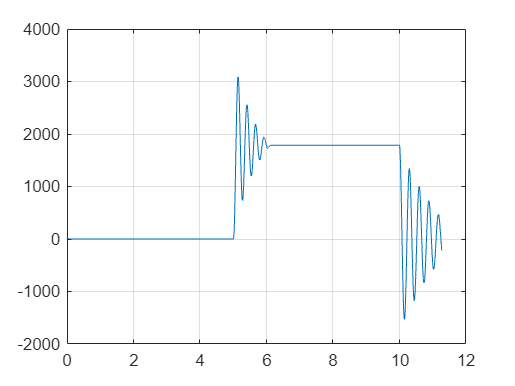

clear; 
close all; clc; 
load('econder1_hold_07-Feb-2025 09_35_19')


plot(time,enc1)
grid on 
box on

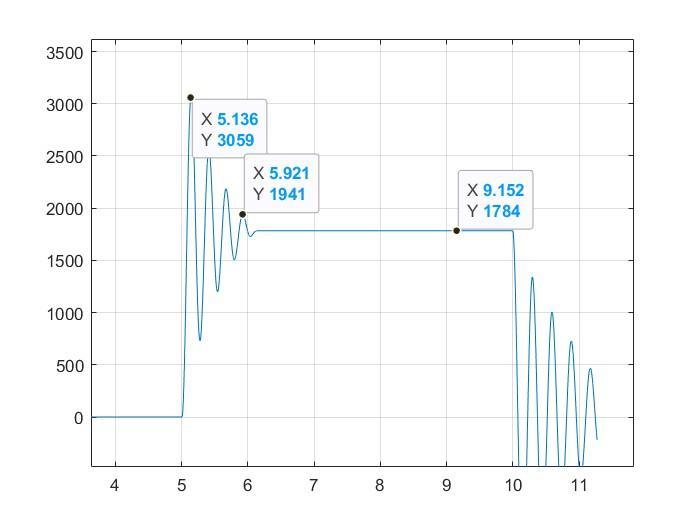

clear; clc; close all;
% PART 1
U = 0.6;
% hardcoded from graph
n = 4;
y_0 = 3059;
t_0 = 5.136;
y_n = 1941;
t_n = 5.921;
y_inf = 1784;

w_hat_d = 2*pi*(n/(t_n - t_0));

beta_w_n = 1/(t_n - t_0)*log((y_0 - y_inf)/(y_n - y_inf));

w_hat_n = norm(w_hat_d, beta_w_n);

beta_hat = beta_w_n/w_hat_n;

U = 0.6000

y_inf = 1784


U
y_inf

k_hat = U/y_inf

k_hat = 3.3632e-04

m_hat = k_hat/(w_hat_n^2) % m1

m_hat = 3.2811e-07

d_hat = k_hat*(2*beta_hat/w_hat_n)% d1

d_hat = 1.7508e-06

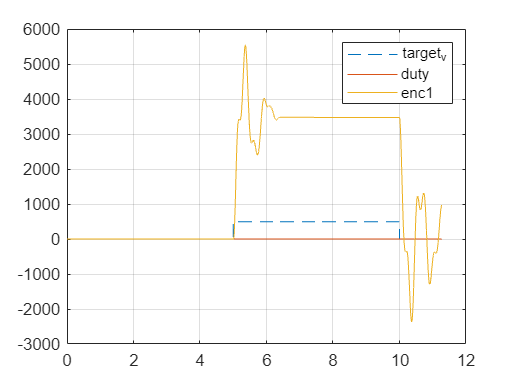

clear; clc; close all;
load('Find_k1.mat')

% PART 2
% looking after the oscillations for the k1 value

plot(time,target_v,'--'); hold on
plot(time,duty)
plot(time,enc1)

legend('target_v', 'duty', 'enc1')

grid on 
box on


% hard coding values 
disp = 3475 % disp from the enc1 (counts_

disp = 3475

force = 491 % voltage (from duty cycle)

force = 491



k1 = force/disp

k1 = 0.1413

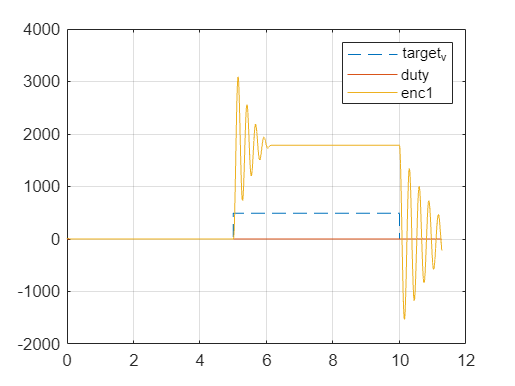

clear; clc; close all; 

% PART 3
% held m1 in place, applied unknown force onto m2
% option: isolating for k2
load('test3_holding_m1_econder1_hold_07-Feb-2025 09_35_19.mat')


plot(time,target_v,'--'); hold on
plot(time,duty)
plot(time,enc1)

legend('target_v', 'duty', 'enc1')

grid on 
box on



U = 0.6;
% hardcoded from graph
n = 4;
y_0 = 3087;
t_0 = 5.147;
y_n = 1933;
t_n = 5.911;
y_inf = 1784;

w_hat_d = 2*pi*(n/(t_n - t_0));
beta_w_n = 1/(t_n - t_0)*log((y_0 - y_inf)/(y_n - y_inf));
w_hat_n = norm(w_hat_d, beta_w_n);
beta_hat = beta_w_n/w_hat_n;

k1 = 0.1413 % from part 2

k_hat = 3.3632e-04 - k1 % k2

k_hat = 3.3632e-04

m_hat =  (k_hat) *(1/w_hat_d)

m_hat = 1.0224e-05


d_hat = k_hat* 2 * (2*beta_hat/m_hat) % d2

d_hat = 11.3533

k1 = 0.1413
k2 = 0.2752
k_hat = 3.3632e-04